# Population analysis

In this script, we load the population data and compute summary statistics and visualisations.

## Clear workspace and add repositories to path


clear all
addpath(genpath('./attention-parietal-dopamine'))
addpath(genpath('./plotj'))

## Directories

Set data directories

subjects = {'J','W'};
path_data = ['C:\Jochem\Gratc_PPC_DA_new\data\processed'];
% path_data = ['/Users/jochemvankempen/NCL/gratc_DA/processed'];
path_population = regexprep(path_data,'processed','population');

if ~isfolder(path_population)
    mkdir(path_population)
end

fprintf('Load data from: %s\n', path_data)

Load data from: C:\Jochem\Gratc_PPC_DA_new\data\processed


fprintf('Store data to: %s\n', path_population)

Store data to: C:\Jochem\Gratc_PPC_DA_new\data\population


## Param

label_drug = {'Dopamine','SCH23390'};
label_drug_ext = {'',' (D1-antagonist)'};
label_attention = {'Attend RF','Attend away'};
label_drug_onoff = {'Drug off','Drug on'};
label_unittype = {'Narrow','Broad'};

markersize = 20; % scatterplot markersize

plot_conventions = 'Science'; % follow figure conventions from this journal

% condition indices
idx_attention_cond = [1 0 0 1 0 0]; % cond_num mapping to attend RF/away in trialdata
idx_attention_roc = [1 1 0 1 1 0]; % see condition comparisons in spike_rate_ROC.m

## Get recordinglist

Compile list of recordings from `recinfo.mat` in each session folder

recordinglist = get_recordinglist(subjects, path_data);
fprintf('Loaded %d recordings \n', height(recordinglist))

Loaded 47 recordings 


## Get population data

Compile population data matrices/tables

[rate_summary, unitlist] = get_population_data(recordinglist, 'spike_rate_summary', path_data, 'dim', 'block_change(1-Inf)');
rate_PSTH = get_population_data(recordinglist, 'spike_rate_PSTH', path_data, 'dim');
rate_ANOVA = get_population_data(recordinglist, 'spike_rate_ANOVA', path_data, 'dim');
rate_ROC = get_population_data(recordinglist, 'spike_rate_ROC', path_data, 'dim', 'block_change(1-Inf)');
waveform = get_population_data(recordinglist, 'waveform', path_data);
% pupil_windows = get_population_data(recordinglist, 'pupil_windows', path_data, 'stim');
% pupil_timeseries = get_population_data(recordinglist, 'pupil_timeseries', path_data, 'stim');

RT = get_population_data(recordinglist, 'RT_drug_modulation', path_data, 'stim');


## Extract param

num_rec = size(RT.RT,1);
[num_unit, num_drug, num_cond] = size(rate_summary.rate);

fprintf('Loaded %d units \n',num_unit)

Loaded 88 units 


## Classify cells as narrow or broad spiking

waveform_cutoff = 250;

unit_class = cell(num_unit,1);
unit_class(waveform.peak_to_trough_time <= waveform_cutoff) = label_unittype(1);
unit_class(waveform.peak_to_trough_time > waveform_cutoff) = label_unittype(2);

% fill and define as categorical variable
unitlist.unit_class = categorical(unit_class);

clear unit_class

## Append unitlist

% rename units in sequential order to be able to join to later tables
unitlist.unit = (1:num_unit)'; 

% average over the ejection currents from both barrels
unitlist.EjectCurrent = nanmean(unitlist.EjectCurrent,2);

% append/join with selectivity/ANOVA table
unitlist = join(unitlist, rate_ANOVA.selectivity, 'Keys', 'unit');

% define categorical variables
unitlist.Drug = categorical(cellstr(unitlist.Drug));
unitlist.Subject = categorical(cellstr(unitlist.Subject));

% define datetime variables
unitlist.Date = datetime(unitlist.Date, 'Format', "yyyy-MM-dd");

## Create population tables: cond

table for all conditions

% number of elements in table
t_numel = num_unit*num_drug*num_cond;

% reshape matrices to single columns
t_rate          = reshape(rate_summary.rate, [t_numel, 1]);
t_FF            = reshape(rate_summary.FF, [t_numel, 1]);
t_roc_attend    = reshape(rate_ROC.roc_attend, [t_numel, 1]);
t_mi_attend     = reshape(rate_ROC.mi_attend, [t_numel, 1]);

% reshape PSTH to similar structure
t_PSTH          = reshape(rate_PSTH.samples, [t_numel, length(rate_PSTH.time)]);
% convert to timeseries object
% t_PSTH = timeseries(t_PSTH,rate_PSTH.time)


% create metadata columns
[t_cond, t_att, t_att_roc] = deal(NaN(size(rate_summary.rate)));
for i = 1:num_cond
    t_cond(:,:,i) = i;
    t_att(:,:,i) = idx_attention_cond(i);
    t_att_roc(:,:,i) = idx_attention_roc(i);
end

t_unit = (1:num_unit)';
t_unit = repmat(t_unit, [1, num_drug, num_cond]);

t_drug_on = [0 1];
t_drug_on = repmat(t_drug_on, [num_unit, 1, num_cond]);

t_unit      = reshape(t_unit, [t_numel, 1]);
t_cond      = reshape(t_cond, [t_numel, 1]);
t_drug_on   = reshape(t_drug_on, [t_numel, 1]);
t_att       = reshape(t_att, [t_numel, 1]);
t_att_roc   = reshape(t_att_roc, [t_numel, 1]);

[t_att_label,t_drug_on_label] = deal(cell(length(t_att),1));
t_att_label(t_att==1) = label_attention(1);
t_att_label(t_att==0) = label_attention(2);

t_drug_on_label(t_drug_on==0) = label_drug_onoff(1);
t_drug_on_label(t_drug_on==1) = label_drug_onoff(2);

% build table
cond_table = table(...
    t_unit, ...
    t_drug_on_label, t_cond, t_att_label, t_att_roc, ...
    t_rate, t_FF, ... % rate, FF
    t_roc_attend, t_mi_attend, ... % roc, MI
    t_PSTH, ... % PSTH
    'VariableNames', {'unit', 'drug_on', 'cond', 'attention', 'attention_roc', 'rate', 'FF', 'roc_attend', 'MI_attend', 'PSTH'});

% join tables 
cond_table = join(cond_table, unitlist, 'Keys', 'unit');

% define categorical variables
cond_table.drug_on = categorical(cond_table.drug_on);
cond_table.cond = categorical(cond_table.cond);
cond_table.attention = categorical(cond_table.attention);
cond_table.attention_roc = categorical(cond_table.attention_roc);

% clear
clear t_*

% print head
disp(head(cond_table))

    unit    drug_on     cond    attention    attention_roc     rate       FF      roc_attend    MI_attend         PSTH          Subject    Task        Date         Drug      EjectCurrent    Weight    unit_class      s_stim        s_att         s_dru         s_dir       s_att*dru    s_att*dir     s_dru*dir    s_att*dru*dir
    ____    ________    ____    _________    _____________    ______    ______    __________    _________</

## Create population tables: attention

table for attention conditions

% number of elements in table
t_numel = num_unit*num_drug*2;

% compute attention averages
t_rate(:,:,1) = mean(rate_summary.rate(:,:,idx_attention_cond==1),3);
t_rate(:,:,2) = mean(rate_summary.rate(:,:,idx_attention_cond==0),3);

t_FF(:,:,1) = mean(rate_summary.FF(:,:,idx_attention_cond==1),3);
t_FF(:,:,2) = mean(rate_summary.FF(:,:,idx_attention_cond==0),3);

t_roc_attend(:,:,1) = mean(rate_ROC.roc_attend(:,:,idx_attention_roc==1),3);
t_roc_attend(:,:,2) = mean(rate_ROC.roc_attend(:,:,idx_attention_roc==0),3);

t_mi_attend(:,:,1) = mean(rate_ROC.mi_attend(:,:,idx_attention_roc==1),3);
t_mi_attend(:,:,2) = mean(rate_ROC.mi_attend(:,:,idx_attention_roc==0),3);

t_PSTH(:,:,1,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==1,:),3);
t_PSTH(:,:,2,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==0,:),3);

t_gain = rate_ROC.gain;

% create metadata columns
[t_att] = deal(zeros(size(t_rate)));
t_att(:,:,1) = 1;

t_unit = (1:num_unit)';
t_unit = repmat(t_unit, [1, num_drug, 2]);

t_drug_on = [0 1];
t_drug_on = repmat(t_drug_on, [num_unit, 1, 2]);

t_unit      = reshape(t_unit, [t_numel, 1]);
t_drug_on   = reshape(t_drug_on, [t_numel, 1]);
t_att       = reshape(t_att, [t_numel, 1]);

[t_att_label,t_drug_on_label] = deal(cell(length(t_att),1));
t_att_label(t_att==1) = label_attention(1);
t_att_label(t_att==0) = label_attention(2);

t_drug_on_label(t_drug_on==0) = label_drug_onoff(1);
t_drug_on_label(t_drug_on==1) = label_drug_onoff(2);

% reshape matrices to single columns
t_rate          = reshape(t_rate, [t_numel, 1]);
t_FF            = reshape(t_FF, [t_numel, 1]);
t_roc_attend    = reshape(t_roc_attend, [t_numel, 1]);
t_mi_attend     = reshape(t_mi_attend, [t_numel, 1]);
t_gain          = reshape(t_gain, [t_numel, 1]);

t_PSTH          = reshape(t_PSTH, [t_numel, length(rate_PSTH.time)]);

% build table
att_table = table(...
    t_unit, ...
    t_drug_on_label, t_att_label, ...
    t_rate, t_FF, ... % rate, FF
    t_roc_attend, t_mi_attend, t_gain, ... % roc, MI, gain
    t_PSTH, ... % PSTH
    'VariableNames', {'unit', 'drug_on', 'attention', 'rate', 'FF', 'roc_attend', 'MI_attend', 'gain', 'PSTH'});

% join tables 
att_table = join(att_table, unitlist, 'Keys', 'unit');

% define categorical variables
att_table.drug_on = categorical(att_table.drug_on);
att_table.attention = categorical(att_table.attention);

% clear
clear t_*
% y = [];
% y_drug=[];
% for idrug = 1:2
%     for iatt = 1:2
%         
%         y = [y ; rate_ROC.gain(:,idrug,iatt)];
%         
%         y_drug = [y_drug; t_drug_on(:,idrug,iatt)];
%         
%         
%     end
% end

% print head
disp(head(att_table))

    unit    drug_on     attention     rate       FF      roc_attend    MI_attend      gain           PSTH          Subject    Task        Date         Drug      EjectCurrent    Weight    unit_class      s_stim        s_att         s_dru         s_dir       s_att*dru    s_att*dir     s_dru*dir    s_att*dru*dir
    ____    ________    _________    ______    ______    __________    _________    ________    _______________    _____

## Print summary of data

Here we list the proportion of units that were selective for various 

fprintf('UNITS\n')

UNITS


fprintf('\tRecorded %d units\n', height(unitlist))

	Recorded 88 units



fprintf('SUBJECTS\n')

SUBJECTS


M1 = strcmpi(unitlist.Subject, {'W'});
M2 = strcmpi(unitlist.Subject, {'J'});
fprintf('\tRecorded %d/%d units from monkey 1/2\n', length(find(M1)), length(find(M2)))

	Recorded 0/0 units from monkey 1/2



fprintf('SELECTIVITY\n')

SELECTIVITY


unit_selectivity = get_unit_selectivity(unitlist, 'visual');
selective_visual = length(find(unit_selectivity));
fprintf('\t%d units with visual response (%1.1f%%)\n', selective_visual, selective_visual/num_unit*100)

	76 units with visual response (86.4%)


unit_selectivity = get_unit_selectivity(unitlist, 'att');
selective_attention = length(find(unit_selectivity));
fprintf('\t%d units with attentional modulation (%1.1f%%)\n', selective_attention, selective_attention/num_unit*100)

	74 units with attentional modulation (84.1%)


% unit_selectivity = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, 'visual&att');
% selective_visAtt = length(find(unit_selectivity));
%
% unit_selectivity = selectData(unitlist, 'visualDrug', 'NA', allSelectivity);
% selective_visDrug = length(find(unit_selectivity));

fprintf('DRUG\n')

DRUG


selective_drug = 0;
selective_attdrug = 0;
selective_interaction = 0;
for idrug = 1:length(label_drug)
    
    num_drug_units = strcmpi(unitlist.Drug, label_drug(idrug)); % total units recorded with this drug
    
    unit_selectivity = get_unit_selectivity(unitlist, 'dru',{'drug',label_drug(idrug)});
    
    fprintf('\tRecorded %d/%d (%d) units from monkey with %s 1/2\n', length(find(M1 & num_drug_units)), length(find(M2 & num_drug_units)), length(find(num_drug_units)), label_drug{idrug})
    
    selective_drug = selective_drug+length(find(unit_selectivity));
    fprintf('\t%d units modulated by %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
    
    unit_selectivity = get_unit_selectivity(unitlist, 'att&dru',{'drug',label_drug(idrug)});
    selective_attdrug = selective_attdrug+length(find(unit_selectivity));
    fprintf('\t%d units modulated by attention and drug %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
    
    unit_selectivity = get_unit_selectivity(unitlist, 'att*dru',{'drug',label_drug(idrug)});
    selective_interaction = selective_interaction+length(find(unit_selectivity));
    fprintf('\t%d units interaction with attention %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
end

	Recorded 0/0 (0) units from monkey with Dopamine 1/2


	36 units modulated by Dopamine (Inf%)


	31 units modulated by attention and drug Dopamine (Inf%)


	4 units interaction with attention Dopamine (Inf%)


	Recorded 0/0 (0) units from monkey with SCH23390 1/2


	14 units modulated by SCH23390 (Inf%)


	14 units modulated by attention and drug SCH23390 (Inf%)


	5 units interaction with attention SCH23390 (Inf%)


fprintf('\t%d total units modulated by attention  (%1.1f%%)\n', selective_attention, selective_attention/num_unit*100)

	74 total units modulated by attention  (84.1%)


fprintf('\t%d total units modulated by drug application  (%1.1f%%)\n', selective_drug, selective_drug/num_unit*100)

	50 total units modulated by drug application  (56.8%)


fprintf('\t%d total units modulated by drug application and attention  (%1.1f%%)\n', selective_attdrug, selective_attdrug/num_unit*100)

	45 total units modulated by drug application and attention  (51.1%)


fprintf('\t%d total units interaction attention by drug application  (%1.1f%%)\n', selective_interaction, selective_interaction/num_unit*100)

	9 total units interaction attention by drug application  (10.2%)


## Plot population histogram and example unit

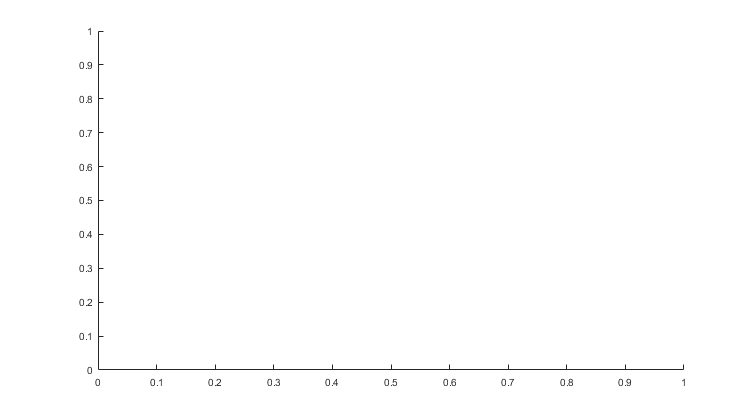

colors = get_colors('att_drug');
linestyle = {'-','--'};


events = {'stim', 'cue', 'dim'};
label_event = {'Stimulus onset', 'Cue onset', 'First-dimming'};
xlabel_event = {{'Time from','stimulus onset (ms)'}, {'Time from','cue onset (ms)'}, {'Time from','first-dimming (ms)'}};
xlim2use = {[-200 750], [-100 750], [-1000 200]};
ylim2use = [25 90];
ncol = length(label_event) + 2;
nrow = length(label_drug);

idx_subplot = {1,2,3,6,7,8,[4 5 9 10]};

[fH, fSet] = plotj_initFig('width', 20, 'height', 11, 'Journal',plot_conventions);

fSet.subplotGap2 = fSet.subplotGap .* [1.3 0.30];

iplot = 0;
for irow = 1:nrow
    
    idx_unit = get_unit_selectivity(att_table, 'att&dru', {'drug',label_drug(irow)});
    
    clear h
    for ievent = 1:length(label_event)
        iplot = iplot+1;
        
        rate_PSTH = get_population_data(recordinglist, 'spike_rate_PSTH', path_data, events{ievent});
        
        times = rate_PSTH.time;
        samples = rate_PSTH.samples;
        
        subtightplot(nrow, ncol, idx_subplot{iplot}, fSet.subplotGap2, fSet.subplotMargin, fSet.subplotMargin)
        if ievent==1 && irow==1
            plotj_initAx(fSet, 'axlabel', irow, 'axlabelDisplacement', [0.07, 0.00]);
        else
            plotj_initAx(fSet);
        end
        
        if ievent==(ceil(length(label_event)/2))
            ht = title([label_drug{irow} label_drug_ext{irow}], 'FontSize', fSet.Fontsize_title);
            %             ht.Position = ht.Position + [0.05 0 0];
        end
        if (ievent~=1)
            axh = get(gca);
            axh.YTick = [];
            axh.YAxis.Visible = 'off'; % remove y-axis
            %             axes('Color','none','YColor','none')
            %             set(gca,'xtick',[])
        end
        hold on
        
        icol = 0;
        for iatt = 1:2
            for idrug = 1:2
                
                idx_attention = att_table.attention==label_attention(iatt);
                idx_drug = att_table.drug_on==label_drug_onoff(idrug);
                
                idx = idx_unit & idx_attention & idx_drug;
                
                PSTH = att_table.PSTH(idx,:);
                
                icol = icol+1;
                h(icol) = boundedline(times, ...
                    squeeze(mean(PSTH,1)), ...
                    squeeze(std(PSTH,[],1))/sqrt(size(PSTH,1)), ...
                    'cmap', colors(iatt,idrug,:), 'alpha');
                set(h(icol), 'LineWidth', fSet.LineWidth)
                set(h(icol), 'LineStyle', linestyle{idrug})
                
                text_legend{icol} = sprintf('%s, %s', label_attention{iatt}, label_drug_onoff{idrug});
                
            end
        end
        xlim(xlim2use{ievent})
        ylim(ylim2use)
        
        if ievent==1
            ylabel('Normalized firing rate (%)', 'FontSize', fSet.Fontsize_text)
            
            text(200, 30, sprintf('n=%d', size(PSTH,1)))
        elseif ievent==3
            if 0%irow==1
                hleg = legend(h, legend_text, 'FontSize', fSet.Fontsize_text, 'Box', 'Off');
                hleg.Position = hleg.Position + [0.05 0.15 0 0];
            end
        end
        
        if irow==nrow
            xlabel(xlabel_event{ievent}, 'FontSize', fSet.Fontsize_text)
        end
    end
    
    
end

Unrecognized function or variable 'att_table'.

hleg = legend(h, text_legend, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'Location', 'NorthWest');
hleg.Position = hleg.Position + [-0.04 0.53 0 0];


% plot example cell, plot raster for example cell, only drug/attention
% ------------------------------------------------------------------------
% plot param
iplot = iplot+1;
axH = subtightplot(nrow, ncol, idx_subplot{iplot}, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
hold on
plotj_initAx(fSet, 'axlabel', 2, 'axlabelDisplacement', [0.07, 0.00]);
yoffset = 100;


% load data
event2plot = 3;
% rec2plot = {'W','2015-10-16'};
rec2plot = {'W','2015-10-01'};
unit2plot = 65;

idx_unit = unitlist.Subject==rec2plot{1} ...
    & unitlist.Date==rec2plot{2} ...
    & (unitlist.unit==unit2plot);

loadfilename = fullfile(path_data, string(unitlist.Subject(idx_unit)), string(unitlist.Date(idx_unit)), 'unit.mat');
unit = load(loadfilename);
loadfilename = fullfile(path_data, string(unitlist.Subject(idx_unit)), string(unitlist.Date(idx_unit)), 'trialdata.mat');
load(loadfilename);
% [trialdata, unit] = remove_excluded_trials(trialdata, unit, unit2plot);

% select only trial window for which this unit has spikes
sps = unit.Dim1Align;

% raster for each condition
idx_attend = idx_attention([trialdata.cond_num])';
idx_drug = [trialdata.drug]' + 1;
ymax = 0;
for iatt = 1:length(unique(idx_attention))
    for idrug = 1:2
        
        % get trial indices
        trial_index = (...
            idx_drug==idrug) ...
            & idx_attend==iatt;
        
        [xspikes, yspikes] = spike_raster( sps(:,trial_index), xlim2use{event2plot}, unit2plot);
        
        x = rate_PSTH.time;
        y = squeeze(mean(rate_PSTH.samples(idx_unit,idrug,idx_attention==iatt,:),3));
        h(icol) = plot(x, y, 'Color', colors(iatt,idrug,:), 'linew', fSet.LineWidth, 'LineStyle', linestyle{idrug});
        
        plot(xspikes, yspikes+yoffset+ymax, 'Color', colors(iatt,idrug,:), 'linew', 1.5)
        
        ymax = ymax + max(yspikes(:));
    end
end
plot([-500 0], [10 10], 'Color', [0.5 0.5 0.5], 'linew', 5)
set(gca,'YTick',[0 yoffset],'YTicklabel',[0 round(rate_PSTH.maxhist(idx_unit)*1000)]);
xlabel('Time from first-dimming (ms)', 'FontSize', fSet.Fontsize_text)
ylabel('Firing rate (Hz)', 'FontSize', fSet.Fontsize_text)

xlim([-800 200])
ylim2use = yoffset+ymax+80;
ylim([0 ylim2use])

p = [rate_ANOVA.selectivity.att(idx_unit) rate_ANOVA.selectivity.dru(idx_unit) rate_ANOVA.selectivity.("att*dru")(idx_unit)];
[pstring,starstring] = get_significance_strings(p, 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
text(axH, -750, ylim2use*0.95, pstring, 'FontSize', fSet.Fontsize_text)

% save
savefigname = fullfile(path_population, sprintf('Population_hist'));
plotj_saveFig(savefigname, {'png', 'svg', 'pdf'})

## plot histogram cell-widths

colors = fSet.colors(1:2,:); % colour

colors = get_colors('spikewidth');


binsize = 25;
binedges = 50:binsize:600;

assert(any(ismember(binedges,waveform_cutoff)), 'threshold needs to be included in binedges')

[fH, fSet] = plotj_initFig('width', 20, 'height', 12, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

ncol=4;
nrow=2;

subtightplot(nrow, ncol, 1, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
plotj_initAx(fSet, 'axlabel', 1, 'axlabelDisplacement', [0.07, 0.01]);
hold on

x = waveform.time-(7*6*5.4);
plot(x, waveform.waveform(unit_class==1, :)*-1, 'Color', [colors(1,:) 0.5])
plot(x, waveform.waveform(unit_class==2, :)*-1, 'Color', [colors(2,:) 0.5])

xlabel(['Time from peak of spike (' plotj_symbol('mu') 's)'], 'FontSize', fSet.Fontsize_text)
ylabel(['Normalized voltage'], 'FontSize', fSet.Fontsize_text)

xlim(minmax(waveform.time) + [0 -200] - 7*6*5.4 )
axis square

subtightplot(nrow, ncol, 2, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
plotj_initAx(fSet, 'axlabel', 2, 'axlabelDisplacement', [0.07, 0.01]);
hold on

h = plotj_hist({waveform.peak_to_trough_time(unit_class==1), waveform.peak_to_trough_time(unit_class==2)}, ...
    'bins', binedges, ...
    'EdgeColor', colors, ...
    'histstyle', 'stairs',...
    'plotmean', 0, ...
    'LineWidth', fSet.LineWidth);

xlabel(['Peak to through time (' char(181) 's)'], 'FontSize', fSet.Fontsize_text)
ylabel('Number of cells', 'FontSize', fSet.Fontsize_text)
axis square

hleg = legend(h, {'Narrow','Broad'}, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'AutoUpdate', 'Off', 'Location', 'East');
hleg.Position = hleg.Position + [0.08 0 0 0];

% do hartigan's dip test to see whether there is a significant dip in this
% distribution
% [dip, p_value, xlow,xup]=HartigansDipSignifTest(allSpikeWaveform.width(idx_unit),5000);
[dip, p_value, xlow, xup, boot_dip]=CalibratedHartigansDipSignifTest(waveform.peak_to_trough_time, 10000);


p_string = get_significance_strings(p_value, 'round', 0);
h_text(1) = text(400, 13, {'Calibrated Hartigan''s dip test:', p_string}, 'FontSize', fSet.Fontsize_text);

savefigname = fullfile(path_population, sprintf('Population_broadNarrow'));
plotj_saveFig(savefigname, {'png', 'svg'})

## Violin, population plot

data2plot = 'rate';
% data2plot = 'FF';
data2plot = 'gain';

[colors_violin, labels_violin] = get_colors('att_drug');
colors_violin = reshape(colors_violin, [4,3]);
labels_violin = reshape(labels_violin, [4,1]);

colors_scatter = get_colors('spikewidth');
markerstyle = {'o','v'};

% selectivity_criterium = 'none';
selectivity_criterium = 'dru';
% selectivity_criterium = 'att&dru';


% plotting and post-hoc tests
ncol = 2;
nrow = 2; % rate, FF
iplot = 0;

idx_subplot = [1 2 ncol+1 ncol+2 ; 3 4 ncol+3 ncol+4] ;
idx_axlabel = [1 NaN 2 NaN ; 3 NaN 4 NaN]+2;

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 20, 'height', 12, 'Journal',plot_conventions);


for idrug = 1:num_drug
    
    
    % fit model 
    fprintf('Testing model: rate, %s \n', label_drug{idrug})
    
    idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
    fprintf('\t Found %d independent units \n',  length(unique(att_table.unit(idx_unit))))
    
    % model fit, firing rate
    lme_rate = fitlme(att_table(idx_unit,:),['rate ~ 1 + attention*drug_on*unit_class + (1|unit)']); % fit interaction model
    lme_FF = fitlme(att_table(idx_unit,:),['FF ~ 1 + attention*drug_on*unit_class + (1|unit)']); % fit interaction model
    
    lme_gain = fitlme(att_table(idx_unit,:),['gain ~ 1 + attention*drug_on*unit_class + (1|unit)']); % fit interaction model
    lme_roc = fitlme(att_table(idx_unit,:),['roc_attend ~ 1 + attention*drug_on*unit_class + (1|unit)']); % fit interaction model
        
    lme_gain = fitlme(att_table(idx_unit,:),['gain ~ 1 + attention*drug_on + (1|unit)']); % fit interaction model

### plot, violinplot for each unitclass

    for iunitc = 1:length(label_unittype) % for each unit_class
        
        
        iplot = iplot+1;
        
        subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
        axH = plotj_initAx(fSet, 'axlabel', iplot, 'axlabelDisplacement', [0.05, 0.02]);
        hold on
        
        idx_unit_class = att_table.unit_class==label_unittype(iunitc);
        
        % extract smaller table
        v_att_table = att_table(idx_unit & idx_unit_class, ismember(att_table.Properties.VariableNames, {data2plot,'drug_on','attention','unit'}));
        fprintf('\t Found %d independent units in unit_class %d \n',  length(unique(v_att_table.unit)), iunitc)

        % define classes 
        plot_class = cell(height(v_att_table),1);
        plot_class( v_att_table.attention==label_attention(1) & v_att_table.drug_on==label_drug_onoff(2) ) = cellstr(sprintf('%s, %s', label_attention{1}, label_drug_onoff{2}));
        plot_class( v_att_table.attention==label_attention(2) & v_att_table.drug_on==label_drug_onoff(2) ) = cellstr(sprintf('%s, %s', label_attention{2}, label_drug_onoff{2}));
        plot_class( v_att_table.attention==label_attention(1) & v_att_table.drug_on==label_drug_onoff(1) ) = cellstr(sprintf('%s, %s', label_attention{1}, label_drug_onoff{1}));
        plot_class( v_att_table.attention==label_attention(2) & v_att_table.drug_on==label_drug_onoff(1) ) = cellstr(sprintf('%s, %s', label_attention{2}, label_drug_onoff{1}));

        v_att_table.plot_class = categorical(plot_class);
        
        % plot violin
        v = violinplot(v_att_table.(data2plot), v_att_table.plot_class, 'ShowMean', true);
        XTickLabel = get(gca,'XTickLabel');
        for iv = 1:length(v)
            v(iv).ScatterPlot.SizeData = 10;
            idx = strcmpi(XTickLabel(iv), labels_violin);
            v(iv).ViolinColor = colors_violin(idx,:);
        end
        
        % fit model
        lme_rate = fitlme(v_att_table,[data2plot ' ~ 1 + attention*drug_on + (1|unit)']); % fit interaction model

        coefficients = lme_rate.Coefficients;
        
        betas = coefficients.Estimate(2:end);
        betas_se = coefficients.SE(2:end);
        p_val = coefficients.pValue(2:end);
        
        p_string = get_significance_strings(p_val, 'rounded', 0);
        betastring = {...
            sprintf('drug: %s = %1.2f%s%1.2f, %s', '\beta', betas(1), '\pm', betas_se(1), p_string{1}), ...
            sprintf('att: %s = %1.2f%s%1.2f, %s', '\beta', betas(2), '\pm', betas_se(2), p_string{2}), ...
            sprintf('att %s drug: %s = %1.2f%s%1.2f, %s', '\times', '\beta', betas(3), '\pm', betas_se(3), p_string{3}), ...
            sprintf('n = %d',length(unique(v_att_table.unit)))};
            
        % plot text
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.95);
        y_pos = get_value_range(tmp_y, 0.95);
        
        h_text = text(x_pos, y_pos, betastring,'HorizontalAlignment','right');        
        
        ylabel('Firing rate (Hz)', 'FontSize', fSet.Fontsize_text)
        set(gca,'XTickLabelRotation',-15)
    end
    
    
    
    
end
% plotting and post-hoc tests
ncol = 2 * (length(label_drug));
nrow = 2; % rate, FF


idx_subplot = [1 2 ncol+1 ncol+2 ; 3 4 ncol+3 ncol+4] ;
idx_axlabel = [1 NaN 2 NaN ; 3 NaN 4 NaN]+2;

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 20, 'height', 12, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

[P, h_text] = deal( NaN(length(label_drug), 2, 2, 2) ); % drugtype, actvity-type, attention, drug-offon,
for idrug = 1:length(label_drug)
        
    iplot=0;
    for irow = 1:nrow
        
        if irow == 1
            % mean rate
            datatype = 'gain';
            data2plot = att_table.gain;
            ylim2use = [0.7 100];
            
            scale ='Log';
            x_text = 0.005;
            y_text = [0.9 0.4];
        elseif irow == 2
            % Fano factor
            datatype = 'FF';
            data2plot = att_table.FF;
            ylim2use = [0 10];
            
            scale ='Linear';
            x_text = 0.1;
            y_text = [0.95 0.1];
        end
        
        for iatt = 1:2
            iplot = iplot+1;
            
            subtightplot(nrow, ncol, idx_subplot(idrug, iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
            axH = plotj_initAx(fSet, 'axlabel', idx_axlabel(idrug, iplot), 'axlabelDisplacement', [0.05, 0.02]);
            hold on
            
            if irow==1 && iatt==1                
                % sup-title
                set(gca,'units','normalized')
                text(100, 400, ['\bf ' label_drug{idrug}], 'FontSize', fSet.Fontsize_title, 'Interpreter', 'tex')
            end

            
            title(sprintf('Attend %s', label_attention{iatt}), 'FontSize', fSet.Fontsize_title)
            
            for iunitc = 1:2
                
                % unit selection
                idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
                idx_att = att_table.attention == categorical(iatt-1);
                idx_unit_class = att_table.unit_class == categorical(iunitc-1);
                
                unit2plot = idx_unit ...
                    & idx_att ...
                    & idx_unit_class;
                
                % extract data
                tmp_data = [data2plot(unit2plot & att_table.drug_on == categorical(0)) ...
                    data2plot(unit2plot & att_table.drug_on == categorical(1))];
                          
                
                plotj_scatter(tmp_data, ...
                    'markerStyle', markerstyle(iunitc), 'MarkerSize', markersize, ...
                    'markerFaceColor', colors_scatter(iunitc,:), 'markerFaceAlpha', 0.5, ...
                    'markerEdgeColor', colors_scatter(iunitc,:), 'markerEdgeAlpha', 0.5, ...
                    'axislimit', ylim2use);
                
                % stats
                P(idrug,irow,iatt,iunitc) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
                
                % effect size
                d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
                
                % mean difference
                delta_data = tmp_data(:,2)-tmp_data(:,1);
                
                axis square
                p_string = get_significance_strings(P(idrug,irow,iatt,iunitc), 'rounded', 0);
                
                % print result
                fprintf('%s: %s, %s, attend %s: delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
                    datatype, ...
                    label_drug{idrug}, ...
                    label_unittype{iunitc}, ...
                    label_attention{iatt}, ...
                    datatype, ...
                    mean(delta_data), ...
                    std(delta_data)/sqrt(length(tmp_data)), ...
                    p_string, ...
                    d)
                
                % plot text
                tmp_x = get(gca,'xlim');
                tmp_y = get(gca,'ylim');
                
                x_pos = get_value_range(tmp_x, x_text);
                y_pos = get_value_range(tmp_y, y_text(1)-y_text(2)*(iunitc-1));
                
                h_text(idrug,irow,iatt,iunitc) = text(x_pos, y_pos, ...
                    sprintf('%s', p_string), ...
                    'Color', colors_scatter(iunitc,:));
                
                if iatt==2
                    
                    x_pos = get_value_range(tmp_x, 0.6);
                    y_pos = get_value_range(tmp_y, 0.1+0.1*(iunitc-1));
                    
                    text(x_pos, y_pos, sprintf('%s (n=%d)', label_unittype{iunitc}, length(tmp_data)), 'Color', colors_scatter(iunitc,:));
                end
            end
            
            
            xlim(ylim2use)
            ylim(ylim2use)
            set(gca,'YScale', scale, 'XScale', scale)
            % %     set(gca,'', [1 10 100])
            
            if irow == 1
                set(gca,'Xtick', [1 10 100], 'XTickLabel', [1 10 100])
                set(gca,'Ytick', [1 10 100], 'YTickLabel', [1 10 100])
                
                xlabel('Firing rate no drug (Hz)','FontSize', fSet.Fontsize_text)
                
                if idrug==1 && iatt==1
                    ylabel('Firing rate drug (Hz)','FontSize', fSet.Fontsize_text)
                end
            elseif irow == 2
                xlabel('Fano Factor no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Fano Factor drug','FontSize', fSet.Fontsize_text)
                end
            end
        end
    end
end

[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');


savefigname = fullfile(path_population, sprintf('mean_rate_FF_drug'));
plotj_saveFig(savefigname, {'png', 'svg'})

## mean rate, Fano factor, drugs

colors = get_colors('spikewidth');
markerstyle = {'o','v'};

% selectivity_criterium = 'none';
selectivity_criterium = 'dru';
selectivity_criterium = 'att&dru';

% plotting and post-hoc tests
ncol = 2 * (length(label_drug));
nrow = 2; % rate, FF


idx_subplot = [1 2 ncol+1 ncol+2 ; 3 4 ncol+3 ncol+4] ;
idx_axlabel = [1 NaN 2 NaN ; 3 NaN 4 NaN]+2;

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 20, 'height', 12, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

[P, h_text] = deal( NaN(length(label_drug), 2, 2, 2) ); % drugtype, actvity-type, attention, drug-offon,
for idrug = 1:length(label_drug)
    
    % unit selection
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    
    iplot=0;
    for irow = 1:nrow
        
        if irow == 1
            % mean rate
            datatype = 'rate';
            data2plot = rate_summary.rate;
            ylim2use = [0.7 100];
            
            scale ='Log';
            x_text = 0.005;
            y_text = [0.9 0.4];
        elseif irow == 2
            % Fano factor
            datatype = 'FF';
            data2plot = rate_summary.FF;
            ylim2use = [0 10];
            
            scale ='Linear';
            x_text = 0.1;
            y_text = [0.95 0.1];
        end
        
        for iatt = 1:2
            iplot = iplot+1;
            
            subtightplot(nrow, ncol, idx_subplot(idrug, iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
            axH = plotj_initAx(fSet, 'axlabel', idx_axlabel(idrug, iplot), 'axlabelDisplacement', [0.05, 0.02]);
            hold on
            
            if irow==1 && iatt==1                
                % sup-title
                set(gca,'units','normalized')
                text(100, 400, ['\bf ' label_drug{idrug}], 'FontSize', fSet.Fontsize_title, 'Interpreter', 'tex')
            end

            
            title(sprintf('Attend %s', label_attention{iatt}), 'FontSize', fSet.Fontsize_title)
            
            for iunitc = 1:2
                unit2plot = idx_unit & unitlist.unit_class==categorical(iunitc-1);
                
                % extract data
                tmp_data = squeeze(mean(data2plot(unit2plot,:,idx_attention==(iatt-1)),3));
                
                plotj_scatter(tmp_data, ...
                    'markerStyle', markerstyle(iunitc), 'MarkerSize', markersize, ...
                    'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
                    'markerEdgeColor', colors(iunitc,:), 'markerEdgeAlpha', 0.5, ...
                    'axislimit', ylim2use);
                
                % stats
                P(idrug,irow,iatt,iunitc) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
                
                % effect size
                d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
                
                % mean difference
                delta_data = tmp_data(:,2)-tmp_data(:,1);
                
                axis square
                p_string = get_significance_strings(P(idrug,irow,iatt,iunitc), 'rounded', 0);
                
                % print result
                fprintf('%s: %s, %s, attend %s: delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
                    datatype, ...
                    label_drug{idrug}, ...
                    label_unittype{iunitc}, ...
                    label_attention{iatt}, ...
                    datatype, ...
                    mean(delta_data), ...
                    std(delta_data)/sqrt(length(find(unit2plot))), ...
                    p_string, ...
                    d)
                
                % plot text
                tmp_x = get(gca,'xlim');
                tmp_y = get(gca,'ylim');
                
                x_pos = get_value_range(tmp_x, x_text);
                y_pos = get_value_range(tmp_y, y_text(1)-y_text(2)*(iunitc-1));
                
                h_text(idrug,irow,iatt,iunitc) = text(x_pos, y_pos, ...
                    sprintf('%s', p_string), ...
                    'Color', colors(iunitc,:));
                
                if iatt==2
                    
                    x_pos = get_value_range(tmp_x, 0.6);
                    y_pos = get_value_range(tmp_y, 0.1+0.1*(iunitc-1));
                    
                    text(x_pos, y_pos, sprintf('%s (n=%d)', label_unittype{iunitc}, length(find(unit2plot))), 'Color', colors(iunitc,:));
                end
            end
            
            
            xlim(ylim2use)
            ylim(ylim2use)
            set(gca,'YScale', scale, 'XScale', scale)
            % %     set(gca,'', [1 10 100])
            
            if irow == 1
                set(gca,'Xtick', [1 10 100], 'XTickLabel', [1 10 100])
                set(gca,'Ytick', [1 10 100], 'YTickLabel', [1 10 100])
                
                xlabel('Firing rate no drug (Hz)','FontSize', fSet.Fontsize_text)
                
                if idrug==1 && iatt==1
                    ylabel('Firing rate drug (Hz)','FontSize', fSet.Fontsize_text)
                end
            elseif irow == 2
                xlabel('Fano Factor no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Fano Factor drug','FontSize', fSet.Fontsize_text)
                end
            end
        end
    end
end

[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');


savefigname = fullfile(path_population, sprintf('mean_rate_FF_drug'));
plotj_saveFig(savefigname, {'png', 'svg'})

## Attend ROC, drug/no drug, narrow/broad. DrugMI-ejecCurrent

datatype = 'MI';
% datatype = 'AUROC';

colors = get_colors('spikewidth');
markerstyle = {'o','v'};


idx_group = 1;

selectivity_criterium = 'none';
selectivity_criterium = 'att&dru';
% selectivity_criterium = 'dru';
% selectivity_criterium = 'dru';
% selectivity_criterium = 'att';

ncol = length(label_drug);
nrow = 2;

[fH, fSet] = plotj_initFig('width', 20, 'height', 14, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap.*[1.2 .8];

axislim = [0.25 0.9];
[P, h_text] = deal( NaN(length(label_drug), 2) ); % drugtype, unit-type,
[P_roc, h_text_roc] = deal( NaN(length(label_drug), 2) ); % drugtype, unit-type,
iplot=0;
for idrug = 1:length(label_drug)
    iplot = iplot+1;
    
    % unit selection
    idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium, {'drug',label_drug(idrug)});
%     idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium);
    idx_unit_interaction = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, 'att*dru', {'drug',label_drug(idrug)});
    
    % subplot axis
    h_ax_subplot = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
    
    % inset axis
    pos = get(h_ax_subplot, 'Position');
    h_ax_inset = axes('Position', [pos(1)+0.28 pos(2)+0.035 0.1 0.11]) ; % inset
    plotj_initAx(fSet);
    hold on

    
    for iunitc = 1:2
        
        set(fH, 'currentaxes', h_ax_subplot);
        
        unit2plot = idx_unit & unit_class==iunitc;
        unit2plot_interaction = idx_unit_interaction & unit_class==iunitc;
        
        % get data - AUROC
        tmp_data = squeeze(mean(rate_ROC.roc_attend(unit2plot,:,idx_attention_roc==1,idx_group),3));

%         % correct auroc
%         idx = tmp_data(:,1)<0.5;
%         tmp_data(idx,:) = 1-tmp_data(idx,:);
        
        idx_interaction = unit2plot_interaction(unit2plot)+1;
        
%         plotj_scatter(tmp_data, ...
%             'markerStyle', markerstyle, 'MarkerSize', markersize, ...
%             'markerFaceColor', colors(unittype,:), 'markerFaceAlpha', 0.5, ...
%             'markerEdgeColor', colors(unittype,:), 'markerEdgeAlpha', 0.5, ...
%             'axislimit', axislim);
        
        plotj_scatter(tmp_data, ...
            'dataIndex', idx_interaction, ...
            'markerStyle', markerstyle, 'MarkerSize', markersize, ...
            'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
            'markerEdgeColor', colors(iunitc,:), 'markerEdgeAlpha', 0.5, ...
            'axislimit', axislim);        
        % stats
        P(idrug,iunitc) = compare_means(tmp_data(:,1),tmp_data(:,2), 1, 'rank');
        
        axis square
        p_string = get_significance_strings(P(idrug,iunitc), 'rounded', 0);
        
        % mean difference
        delta_data = tmp_data(:,2)-tmp_data(:,1);
        
        % effect size
        d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');

        % print result
        fprintf('%s: %s, %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'AUROC', ...
            label_drug{idrug}, ...
            label_unittype{iunitc}, ...
            'AUROC', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(length(find(unit2plot))), ...
            p_string, ...
            d)

        % set text
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.05);
        y_pos = get_value_range(tmp_y, 0.95 - 0.07 * (iunitc-1));
        
        h_text(idrug,iunitc) = text(x_pos, y_pos, ...
            sprintf('%s, %s (n=%d)', p_string, label_unittype{iunitc}, length(find(unit2plot))), ...
            'Color', colors(iunitc,:), 'FontSize', fSet.Fontsize_ax);

## inset

        idx = tmp_data(:,1)<0.5;
        tmp_data(idx,:) = 1-tmp_data(idx,:);

        P_roc(idrug,iunitc) = compare_means(tmp_data(:,1),tmp_data(:,2), 1, 'rank');

        bar_data = diff(tmp_data,1,2);
        
        bar_y = mean(bar_data);
        bar_y_err = std(bar_data)/sqrt(length(bar_data));
        
        % plot
        set(fH, 'currentaxes', h_ax_inset);
        h_scatter = scatter(iunitc + (rand(length(bar_data),1)-0.5)*0.1, bar_data, ...
            '.', 'MarkerFaceColor', colors(iunitc,:),'MarkerEdgeColor', colors(iunitc,:));
        h_scatter.MarkerFaceAlpha = 0.5;
        h_scatter.MarkerEdgeAlpha = 0.5;

        plot(iunitc + [-0.25 0.25], [bar_y bar_y], 'Color', colors(iunitc,:), 'linew', fSet.LineWidth+1)
        plot(iunitc + [0 0], bar_y + [-bar_y_err bar_y_err], 'Color', colors(iunitc,:), 'linew', fSet.LineWidth)
        
        p_string = get_significance_strings(P_roc(idrug,iunitc), 'rounded', 0);
        
        % mean difference
        delta_data = tmp_data(:,2)-tmp_data(:,1);
        
        % effect size
        d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
        
        % print result
        fprintf('%s: %s, %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'AUROC-CORRECT', ...
            label_drug{idrug}, ...
            label_unittype{iunitc}, ...
            'AUROC', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(length(find(unit2plot))), ...
            p_string, ...
            d)

        
        % set text
        % tmp_y = get(gca,'ylim');
        %y_pos = get_value_range(tmp_y, 0.95);
        y_pos = 0.1*idrug;
        
        h_text_roc(idrug,iunitc) = text(iunitc+0.1, y_pos, ...
            p_string, ...
            'Color', colors(iunitc,:), ...
            'FontSize', fSet.Fontsize_ax);
    end
    
    set(h_ax_inset, 'XTick', [1 2], 'XTickLabel', label_unittype)
%     ylabel(h_ax_inset, [plotj_symbol('Delta') ' | AUROC-0.5 |'],'FontSize', fSet.Fontsize_text)
    ylabel(h_ax_inset, [plotj_symbol('Delta') ' AUROC-c'],'FontSize', fSet.Fontsize_text)

    xlabel(h_ax_subplot, 'Attention AUROC no drug','FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel(h_ax_subplot, 'Attention AUROC drug','FontSize', fSet.Fontsize_text)
    end
end
[p_fdr, p_masked] = FDR(P, 0.05);
[p_fdr, p_masked_corr] = FDR(P_roc, 0.05);

plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');

## drugMI/attAUROC against ejection current

switch datatype
    case 'MI'
        %         data2plot = rate_ROC.mi_drug(:,1);
        data2plot = mean(rate_ROC.mi_drug,2);
        
        iunitc=[];
        
        ylabel2use = 'Drug modulation index';
        ylim2use = [];
    case 'AUROC'
        data2plot = squeeze(diff(rate_ROC.roc_attend,1,2));
        data2plot = squeeze(mean(data2plot(:,idx_attention_roc==1),2)); % average over relevant auroc conditions
        
        iunitc = [];
        
        ylabel2use = [plotj_symbol('Delta') ' attention AUROC'];
        ylim2use = [-0.25 0.3];
end

clear ax h
for idrug = 1%:ncol
    clear text_legend
    iplot=iplot+1;
    
    idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium, {'drug',label_drug(idrug)});
    
    ax(idrug) = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', iplot, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
    
    if ~isempty(iunitc)
        unit2plot = idx_unit & unit_class==iunitc;
    else
        unit2plot = idx_unit;
    end
    length(find(unit2plot))
    
    % ejectionCurrent
    ejection_current = unitlist.EjectCurrent(unit2plot);
    xlabel_event = 'Ejection Current';
    xlim2use = [17 90];
    
    if length(unique(unit_class(unit2plot)))==1
        tmp_data = [ejection_current  data2plot(unit2plot)];
        hscat = plotj_scatter(tmp_data, ...
            'markerStyle', markerstyle, 'markerSize', markersize, ...
            'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
            'axislimit', [], ...
            'unityLine', 0);
        text_legend{1} = [label_unittype{iunitc} ' (n=' num2str(length(find(unit_class(idx_unit)==iunitc))) ')'];
    else
        tmp_data = [ejection_current  data2plot(unit2plot)];
        hscat = plotj_scatter(tmp_data, ...
            'dataIndex', unit_class(unit2plot), ...
            'markerStyle', markerstyle, 'MarkerSize', markersize, ...
            'markerFaceColor', colors(1:2,:), 'markerFaceAlpha', [0.5 0.5], ...
            'markerEdgeColor', colors(1:2,:), 'markerEdgeAlpha', [0.5 0.5], ...
            'axislimit', [], ...
            'unityLine', 0);
        text_legend{1} = [label_unittype{1} ' (n=' num2str(length(find(unit_class(idx_unit)==1))) ')'];
        text_legend{2} = [label_unittype{2} ' (n=' num2str(length(find(unit_class(idx_unit)==2))) ')'];
    end
    
    ejection_current_centered = ejection_current - mean(unique(ejection_current));
    
    data_table = table(ejection_current_centered, data2plot(unit2plot), 'VariableNames', {'x', 'y'});
    [stats2report, predict_data, stats, model] = fitlme_singleVar_sequential(data_table, 0);
    
    predict_data.x = predict_data.x + mean(unique(ejection_current));
    
    switch datatype
        case 'MI'
            filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
        case 'AUROC'
            filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
    end
    writetable(data_table, filename)
    
%     fprintf('Chi(%d) %1.2f, p = %1.3f\n', stats2report.deltaDF, stats2report.LRStat, stats2report.pValue)
    
    if any(strcmp('fit_mean', predict_data.Properties.VariableNames))
        h = plot(predict_data.x, predict_data.fit_mean, 'linewidth', fSet.LineWidth, 'color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_low, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_high, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        [pstring_chi,starstring] = get_significance_strings(stats2report.pValue, 'rounded', 0);
        
        cond1 = exist([filename(1:end-4) '_R.csv'], 'file');
        cond2 = strcmpi(model,'quadratic');
        if cond1 && cond2
            utable = readtable([filename(1:end-4) '_R.csv']);
            
            if utable.usig==1
                pstring_chi = [pstring_chi ' (U^{+})'];
            else
                pstring_chi = [pstring_chi ' (U^{-})'];
            end
        end
        
    else
        pstring_chi = '';
    end
    
    
    switch model
        case 'linear'
            betaString = ['\beta' '_{1} = ' num2str(stats.Estimate, '%1.2e')];
            %         model_color = colors(2,:);
        case 'quadratic'
            betaString = ['\beta' '_{2} = ' num2str(stats.Estimate, '%1.2e')];
        otherwise
            betaString = [];
    end
    
    axis square
    xlabel(xlabel_event, 'FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel(ylabel2use, 'FontSize', fSet.Fontsize_text)
    end
    
    if ~isempty(ylim2use)
        ylim(ylim2use)
    end
    if ~isempty(xlim2use)
        xlim(xlim2use)
    end
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.6);
    y_pos(1) = get_value_range(tmp_y, 0.8);
    y_pos(2) = get_value_range(tmp_y, 0.9);
    
    text(x_pos, y_pos(1), text_legend{1}, 'FontSize', fSet.Fontsize_text, 'Color', colors(1,:))
    text(x_pos, y_pos(2), text_legend{2}, 'FontSize', fSet.Fontsize_text, 'Color', colors(2,:))

    % set ax param
    set(gca,'YDir','reverse')
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.05);
    y_pos = get_value_range(tmp_y, 0.1);
    
    text(x_pos, y_pos, {betaString, pstring_chi }, 'fontsize', fSet.Fontsize_text, 'color', [0.3 0.3 0.3])
    
end

savefigname = fullfile(path_population, sprintf('attAuroc_DrugResponseCurve'));
plotj_saveFig(savefigname, {'png', 'svg'})

## DrugMI-ejecCurrent across selectivity indices

colors = get_colors('spikewidth');

datatype = 'MI';
% datatype = 'AUROC';


selectivity_criteria = {'none', 'att', 'dru', 'att&dru'};
label_criteria = {'No subselection', 'Attention-selective', 'Drug-selective', {'Attention & Drug', 'selective'}};

ncol = length(selectivity_criteria);
nrow = length(label_drug)+1;
iplot = 0;

[fH, fSet] = plotj_initFig('width', 20, 'height', 16, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap.*[1 .75];

idx_subplot = [1:ncol ; (ncol+1):ncol*2; (ncol*2+1):ncol*3];

## drugMI/attAUROC against ejection current

[P,h_text] = deal(zeros(length(selectivity_criteria), length(label_drug)));
[P_population,h_text_population] = deal(zeros(length(selectivity_criteria),1));
for icrit = 1:length(selectivity_criteria)
    
    selectivity_criterium = selectivity_criteria{icrit};
    
    switch datatype
        case 'MI'
            %         data2plot = rate_ROC.mi_drug(:,1);
            data2plot = mean(rate_ROC.mi_drug,2);
            
            iunitc=[];
            
            ylabel2use = 'Drug modulation index';
            ylim2use = [];
        case 'AUROC'
            data2plot = squeeze(diff(rate_ROC.roc_attend,1,2));
            data2plot = squeeze(mean(data2plot(:,idx_attention_roc==1),2)); % average over relevant auroc conditions
            
            iunitc = [];
            
            ylabel2use = [plotj_symbol('Delta') ' attention AUROC'];
            ylim2use = [-0.25 0.3];
    end
    
    clear ax h
    for idrug = 1:length(label_drug)
        clear text_legend
        iplot=iplot+1;
        
        idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium, {'drug',label_drug(idrug)});
        
        ax(idrug) = subtightplot(nrow, ncol, idx_subplot(iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if idrug==1
            plotj_initAx(fSet, 'axlabel', icrit);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if idrug==1
            % title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
            h_title = title(label_criteria{icrit}, 'FontSize', fSet.Fontsize_title);
            set(h_title, 'Units', 'normalized');
            h_title.Position = h_title.Position+[0 0.2 0];
        end
        if ~isempty(iunitc)
            unit2plot = idx_unit & unit_class==iunitc;
        else
            unit2plot = idx_unit;
        end
        
        % ejectionCurrent
        ejection_current = unitlist.EjectCurrent(unit2plot);
        xlabel_event = 'Ejection Current';
        xlim2use = [17 95];
        
        if length(unique(unit_class(unit2plot)))==1
            tmp_data = [ejection_current  data2plot(unit2plot)];
            hscat = plotj_scatter(tmp_data, ...
                'markerStyle', {'.'}, 'markerSize', markersize, ...
                'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
                'axislimit', [], ...
                'unityLine', 0);
            text_legend{1} = [label_unittype{iunitc} ' (n=' num2str(length(find(unit_class(idx_unit)==iunitc))) ')'];
        else
            tmp_data = [ejection_current  data2plot(unit2plot)];
            hscat = plotj_scatter(tmp_data, ...
                'dataIndex', unit_class(unit2plot), ...
                'markerStyle', {'o','o'}, 'MarkerSize', markersize, ...
                'markerFaceColor', colors(1:2,:), 'markerFaceAlpha', [0.5 0.5], ...
                'markerEdgeColor', colors(1:2,:), 'markerEdgeAlpha', [0.5 0.5], ...
                'axislimit', [], ...
                'unityLine', 0);
            text_legend{1} = [label_unittype{1} ' (n=' num2str(length(find(unit_class(idx_unit)==1))) ')'];
            text_legend{2} = [label_unittype{2} ' (n=' num2str(length(find(unit_class(idx_unit)==2))) ')'];
        end
        
        ejection_current_centered = ejection_current - mean(unique(ejection_current));
        
        data_table = table(ejection_current_centered, data2plot(unit2plot), 'VariableNames', {'x', 'y'});
        [stats2report, predict_data, stats, model] = fitlme_singleVar_sequential(data_table, 0);
        P(icrit,idrug) = stats2report.pValue;
        predict_data.x = predict_data.x + mean(unique(ejection_current));
        
        switch datatype
            case 'MI'
                filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s_%s.csv', label_drug{idrug}, selectivity_criteria{icrit}));
            case 'AUROC'
                filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s_%s.csv', label_drug{idrug}, selectivity_criteria{icrit}));
        end
        writetable(data_table, filename);
        
        fprintf('Chi(%d) %1.2f, p = %1.3f\n', stats2report.deltaDF, stats2report.LRStat, stats2report.pValue)
        
        if any(strcmp('fit_mean', predict_data.Properties.VariableNames))
            h = plot(predict_data.x, predict_data.fit_mean, 'linewidth', fSet.LineWidth, 'color', [0.3 0.3 0.3]);
            h = plot(predict_data.x, predict_data.fit_CI_low, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
            h = plot(predict_data.x, predict_data.fit_CI_high, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
            [pstring_chi,starstring] = get_significance_strings(stats2report.pValue, 'rounded', 0);
            
            cond1 = exist([filename(1:end-4) '_R.csv'], 'file');
            cond2 = strcmpi(model,'quadratic');
            if cond1 && cond2
                utable = readtable([filename(1:end-4) '_R.csv']);
                
                if utable.usig==1
                    pstring_chi = [pstring_chi ' (U^{+})'];
                else
                    pstring_chi = [pstring_chi ' (U^{-})'];
                end
            end
            
        else
            pstring_chi = '';
        end
        
        switch model
            case 'linear'
                betaString = ['\beta' '_{1} = ' num2str(stats.Estimate, '%1.2e')];
                %         model_color = colors(2,:);
            case 'quadratic'
                betaString = ['\beta' '_{2} = ' num2str(stats.Estimate, '%1.2e')];
            otherwise
                betaString = [];
        end
        
        axis square
        if idrug==length(label_drug)
            xlabel(xlabel_event, 'FontSize', fSet.Fontsize_text)
        end
        if icrit==1
            ylabel({label_drug{idrug},ylabel2use}, 'FontSize', fSet.Fontsize_text)
        end
        
        if ~isempty(ylim2use)
            ylim(ylim2use)
        end
        if ~isempty(xlim2use)
            xlim(xlim2use)
        end
        
        % plot text indicating number of units
        set(gca, 'Units', 'normalized');
        
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.6);
        y_pos(1) = get_value_range(tmp_y, 0.8);
        y_pos(2) = get_value_range(tmp_y, 0.9);
        
        text(x_pos, y_pos(1), text_legend{1}, 'FontSize', fSet.Fontsize_text, 'Color', colors(1,:))
        text(x_pos, y_pos(2), text_legend{2}, 'FontSize', fSet.Fontsize_text, 'Color', colors(2,:))
        
        % set ax param
        set(gca,'YDir','reverse')
        
        % plot text with stats
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        switch label_drug{idrug}
            case 'Dopamine'
                x_pos = get_value_range(tmp_x, 0.65);
                y_pos = get_value_range(tmp_y, 0.05);
            case 'SCH23390'
                x_pos = get_value_range(tmp_x, 0.05);
                y_pos = get_value_range(tmp_y, 0);
        end
        
        h_text(icrit,idrug) = text(x_pos, y_pos, {betaString, pstring_chi}, 'fontsize', fSet.Fontsize_text, 'color', [0.3 0.3 0.3]);
        
    end

## double fit of lme

    ejection_current = unitlist.EjectCurrent(unit2plot);
    ejection_current_centered = ejection_current - mean(unique(ejection_current));
    idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium);

    tmp_unitlist = unitlist(idx_unit,:);
    idx_drug = strcmpi(tmp_unitlist.Drug, label_drug(2))+1;
    
    data_table = table(ejection_current_centered(idx_unit), data2plot(idx_unit), idx_drug, 'VariableNames', {'x', 'y', 'idx'});
    data_table.idx = categorical(data_table.idx);
    
    switch datatype
        case 'MI'
            filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s.csv', selectivity_criteria{icrit}));
        case 'AUROC'
            filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s.csv', selectivity_criteria{icrit}));
    end
    writetable(data_table, filename);
    
    
    data_table.polyx1 = data_table.x;
    data_table.polyx2 = data_table.x.^2;
    
    data_table.mixed_poly = data_table.polyx1;
    data_table.mixed_poly(idx_drug==1) = data_table.polyx2(idx_drug==1);
    
    
%     lme1 = fitlme(data_table,['y ~ 1 + (1|idx)']);% fit constant
%     lme2 = fitlme(data_table,['y ~ 1 + polyx1 + (1|idx)']); % fit linear model
%     lme3 = fitlme(data_table,['y ~ 1 + polyx1 + (polyx1|idx)']); % fit linear model
%     lme4 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + (polyx1|idx)']); % fit quadratic model (this includes the linear model), note this doesn't have orthogonal contrasts!!    
%     lme4 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + mixed_poly + (1|idx)']); % fit mixed linear/quadratic coefficients
    

    % test interaction between drug idx and linear ejection current
    fprintf('\nInteraction model: linear \n')
    lme1 = fitlme(data_table,['y ~ 1 + (1|idx)']);% fit constant
    lme2 = fitlme(data_table,['y ~ 1 + polyx1 + (1|idx)']); % fit linear model
    lme3 = fitlme(data_table,['y ~ 1 + polyx1 + polyx1*idx + (1|idx)']); % fit interaction model
    lme_li = lme3;
    
    comp1 = compare(lme1, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); % compare linear to constant
    
    fprintf('\t Linear: Chi(%d) %1.2f, p = %1.3f\n', 1, comp1.LRStat(2), comp1.pValue(2))
    fprintf('\t Interaction: Chi(%d) %1.2f, p = %1.3f\n', 1, comp2.LRStat(2), comp2.pValue(2))
    
    
    % test random slopes model between drug idx and linear ejection current
    fprintf('\nRandom slopes model: linear \n')
    lme1 = fitlme(data_table,['y ~ 1 + (1|idx)']);% fit constant
    lme2 = fitlme(data_table,['y ~ 1 + polyx1 + (1|idx)']); % fit linear model
    lme3 = fitlme(data_table,['y ~ 1 + polyx1 + (polyx1|idx)']); % fit random slopes model
    
    comp1 = compare(lme1, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); % compare linear to constant
    
    fprintf('\t Linear: Chi(%d) %1.2f, p = %1.3f\n', 1, comp1.LRStat(2), comp1.pValue(2))
    fprintf('\t Interaction: Chi(%d) %1.2f, p = %1.3f\n', 1, comp2.LRStat(2), comp2.pValue(2))
    

    % test interaction between drug idx and quadratic ejection current
    fprintf('\nInteraction model: quadratic \n')
    lme1 = fitlme(data_table,['y ~ 1 + (1|idx)']);% fit constant
    lme2 = fitlme(data_table,['y ~ 1 + polyx1 + (1|idx)']); % fit linear model
    lme3 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + (1|idx)']); % fit quadratic model (this includes the linear model), note this doesn't have orthogonal contrasts!!    
    lme4 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + polyx2*idx + (1|idx)']); % fit interaction model
    lme_qi = lme4;
    
    comp1 = compare(lme1, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); % compare linear to constant
    comp3 = compare(lme3, lme4, 'CheckNesting',true); % compare linear to constant
    
    fprintf('\t Linear: Chi(%d) %1.2f, p = %1.3f\n', 1, comp1.LRStat(2), comp1.pValue(2))
    fprintf('\t Quadratic: Chi(%d) %1.2f, p = %1.3f\n', 1, comp2.LRStat(2), comp2.pValue(2))
    fprintf('\t Interaction: Chi(%d) %1.2f, p = %1.3f\n', 1, comp3.LRStat(2), comp3.pValue(2))

    
    % test mixed polynomial model
    fprintf('\nMixed-polynomial model \n')
    lme1 = fitlme(data_table,['y ~ 1 + (1|idx)']);% fit constant
    lme2 = fitlme(data_table,['y ~ 1 + polyx1 + (1|idx)']); % fit linear model
    lme3 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + (1|idx)']); % fit quadratic model (this includes the linear model), note this doesn't have orthogonal contrasts!!    
    lme4 = fitlme(data_table,['y ~ 1 + polyx1 + polyx2 + mixed_poly + (1|idx)']); % fit mixed linear/quadratic coefficients

    % compare the model fits
    comp1 = compare(lme1, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); % compare linear to constant
    comp3 = compare(lme3, lme4, 'CheckNesting',true); % compare linear to constant
    
    P_population(icrit) = comp3.pValue(2);
        
    % print results
    fprintf('\t Linear: Chi(%d) %1.2f, p = %1.3f\n', 1, comp1.LRStat(2), comp1.pValue(2))
    fprintf('\t Quadratic: Chi(%d) %1.2f, p = %1.3f\n', 1, comp2.LRStat(2), comp2.pValue(2))
    fprintf('\t Mixed: Chi(%d) %1.2f, p = %1.3f\n', 1, comp3.LRStat(2), comp3.pValue(2))

    
    % compare mixed model to linear and quadratic interaction models
    fprintf('\nMixed-polynomial model - linear interaction \n')
    comp_li_mixed = compare(lme4, lme_li)
    fprintf('\nMixed-polynomial model - quadratic interaction \n')
    comp_qi_mixed = compare(lme4, lme_qi)

    
    % plot text
    iplot=iplot+1;    
    subtightplot(nrow, ncol, idx_subplot(iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet);
    hold on
    axis off
    [pstring_chi] = get_significance_strings(comp3.pValue(2), 'rounded', 0);
    [pstring_coef1] = get_significance_strings(lme4.Coefficients.pValue(2), 'rounded', 0);
    [pstring_coef2] = get_significance_strings(lme4.Coefficients.pValue(3), 'rounded', 0);
    [pstring_coef3] = get_significance_strings(lme4.Coefficients.pValue(4), 'rounded', 0);

    
    
    text2plot = { ...
        sprintf('%s(1) = %1.2f, %s', '\chi', comp3.LRStat(2), pstring_chi), ... # final model fit
        '', ...
        sprintf('%s_{1} = %1.2e, %s', '\beta', lme4.Coefficients.Estimate(2), pstring_coef1), ... # first coefficient
        sprintf('%s_{2} = %1.2e, %s', '\beta', lme4.Coefficients.Estimate(3), pstring_coef2), ... # first coefficient
        sprintf('%s_{3} = %1.2e, %s', '\beta', lme4.Coefficients.Estimate(4), pstring_coef3), ... # first coefficient
        };
    %

    h_text_population(icrit,1) = text(0,0,text2plot,'Interpreter','tex');
    ylim([-0.5 0.5])
    
    if icrit==1
        text(-0.2, 0, ['"Population Model"'], 'Rotation', 90, 'HorizontalAlignment', 'center')
    end

end

% multiple comparison correction, individual models
[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic', 2);
plotj_text_emphasise(h_text, p_masked, 'bold', 2);

% multiple comparison correction, population models
[p_fdr, p_masked] = FDR(P_population, 0.05);
plotj_text_emphasise(h_text_population, p_masked, 'italic', 1);
plotj_text_emphasise(h_text_population, p_masked, 'bold', 1);


% save
savefigname = fullfile(path_population, sprintf('DrugResponseCurve_selection'));
plotj_saveFig(savefigname, {'png', 'svg'})

## plot change in firing rate over the course of a block

selectivity_criteria = {'none', 'att', 'dru', 'att&dru'};
label_criteria = {'No subselection', 'Attention-selective', 'Drug-selective', {'Attention & Drug', 'selective'}};

ncol = length(selectivity_criteria);
nrow = length(label_drug);
iplot = 0;

[fH, fSet] = plotj_initFig('width', 25, 'height', 13, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap.*[1 .75];

idx_subplot = [1:ncol ; (ncol+1):ncol*2];

[P,h_text] = deal(zeros(length(selectivity_criteria), length(label_drug), 2)); % crit, drug, unit

for icrit = 1:length(selectivity_criteria)
    
    selectivity_criterium = selectivity_criteria{icrit};
    
    data2plot = rate_summary.lm.coef(:,:,2);
    
    clear ax h
    for idrug = 1:length(label_drug)
        clear text_legend tmp_data
        iplot=iplot+1;
        
        
        ax(idrug) = subtightplot(nrow, ncol, idx_subplot(iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if idrug==1
            plotj_initAx(fSet);
%             plotj_initAx(fSet, 'axlabel', icrit);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if idrug==1
            % title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
            h_title = title(label_criteria{icrit}, 'FontSize', fSet.Fontsize_title);
            set(h_title, 'Units', 'normalized');
%             h_title.Position = h_title.Position+[0 0.2 0];
        end
        
        idx_unit = get_unit_selectivity(unitlist, rate_ANOVA.selectivity, selectivity_criterium, {'drug',label_drug(idrug)});
        
        % plot per unit type
        tmp_data{1} = data2plot(idx_unit & unit_class==1, 2);
        tmp_data{2} = data2plot(idx_unit & unit_class==2, 2);
        
        plotj_hist(tmp_data, ...
            'dataindex', unit_class(idx_unit), ...
            'histStyle','bar');
        
        % stats
        P(icrit,idrug,1) = compare_means(tmp_data{1},0, 1, 'rank');
        P(icrit,idrug,2) = compare_means(tmp_data{2},0, 1, 'rank');
        
        [pstring1] = get_significance_strings(P(icrit,idrug,1), 'rounded', 0);
        [pstring2] = get_significance_strings(P(icrit,idrug,2), 'rounded', 0);
        
        set(gca, 'Units', 'normalized');
        
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.5);
        y_pos(1) = get_value_range(tmp_y, 0.8);
        y_pos(2) = get_value_range(tmp_y, 0.9);

        h_text(icrit,idrug,1) = text(x_pos, y_pos(1), ...
            sprintf('%s, %s (n=%d)', pstring1, label_unittype{1}, length(find(idx_unit & unit_class==1))), ...
            'Color', colors(1,:), 'FontSize', fSet.Fontsize_text);
        h_text(icrit,idrug,1) = text(x_pos, y_pos(2), ...
            sprintf('%s, %s (n=%d)', pstring2, label_unittype{2}, length(find(idx_unit & unit_class==2))), ...
            'Color', colors(2,:), 'FontSize', fSet.Fontsize_text);
        
        plot([0 0], ylim, 'k', 'linew', 1)
        
        xlabel('beta values')
        ylabel('count')
    end
    

end

% multiple comparison correction, individual models
[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic', 2);
plotj_text_emphasise(h_text, p_masked, 'bold', 2);

% save
savefigname = fullfile(path_population, sprintf('block_drug_response'));
plotj_saveFig(savefigname, {'png', 'svg'})

## plot gain test

selectivity_criterium = 'dru';


[fH, fSet] = plotj_initFig('width', 20, 'height', 8, 'Journal',plot_conventions);

clear legendText h
gain_table_full = [];

iplot=0;
for idrug = 1:length(label_drug)
    iplot = iplot+1;
    
    % unit selection
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    fprintf('Drug: %s, units: %d\n',label_drug{idrug}, length(find(idx_unit)))

%     % subplot axis
%     h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
%     plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.01, 0.02]);
%     hold on
%     
%     title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)

    idratt = 0;
    
    gain_table = [];
    gain_mat = [];
    
    for idrug_in = 1:2
        
        for iatt = 1:2
            idratt = idratt+1;
            text_legend{idratt} = sprintf('Attend %s, Drug %s', label_attention{abs(iatt-3)}, label_drug_onoff{idrug_in});

            y = squeeze(rate_ROC.gain(idx_unit, idrug_in, iatt));
            
            n = length(y);
            idx_attention = zeros(n,1) + iatt;
            idx_drug = zeros(n,1) + idrug_in;
            
            gain_table = [gain_table; table(y,(1:n)',idx_attention,idx_drug,'VariableNames',{'gain','unit','attention','drug'})];
            
        end
    end
    
    lme4 = fitlme(gain_table,['gain ~ 1 + attention*drug + (1|unit)']); % fit interaction

    
end

## plot gain unit

colors = get_colors('spikewidth');
markerstyle = {'o','v'};


idx_group = 1;

selectivity_criterium = 'none';
selectivity_criterium = 'att&dru';
selectivity_criterium = 'dru';
% selectivity_criterium = 'dru';
% selectivity_criterium = 'att';

colors = get_colors('att_drug');

ncol = length(label_drug);
nrow = 1;

[fH, fSet] = plotj_initFig('width', 20, 'height', 8, 'Journal',plot_conventions);

clear legendText h
gain_table_full = [];

iplot=0;
for idrug = 1:length(label_drug)
    iplot = iplot+1;
    
    % unit selection
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    
    % subplot axis
    h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)

## plot errorbar

    iattDrug = 0;
    gain_table = [];
    gain_mat= [];
    colors_mat = [];
    for iatt = 1:2
        for idrug_in = 1:2
            iattDrug = iattDrug+1;
            text_legend{iattDrug} = sprintf('Attend %s, Drug %s', label_attention{iatt}, label_drug_onoff{idrug_in});
            
            y = squeeze(rate_ROC.gain(idx_unit,idrug_in,iatt));
                        
            n = length(find(idx_unit));
            unit = (1:n)';
            cond = repmat(iatt,n,1);
            drug = repmat(idrug_in-1,n,1);
            gain_table = [gain_table ; table(unit,y,cond,drug,repmat(label_drug(idrug),[n,1]),'VariableNames',{'unit','gain','attention','drug_on','drug'})];
            gain_mat = [gain_mat, y];
            colors_mat = [colors_mat ; squeeze(colors(iatt,idrug_in,:))'];
        end
    end

    % define categorical variables
    gain_table.attention = categorical(gain_table.attention);
    gain_table.drug_on = categorical(gain_table.drug_on);
    gain_table.drug = categorical(gain_table.drug);
    
    
    v = violinplot(gain_mat, text_legend, 'ShowMean', true);
    for iv = 1:length(v)
        v(iv).ViolinColor = colors_mat(iv,:);
        v(iv).ScatterPlot.SizeData = 10;
    end

## do stats

check with linear mixed effect model

    lme = fitlme(gain_table,['gain ~ 1 + (1|unit)']);% fit constant
    lme2 = fitlme(gain_table,['gain ~ 1 + attention + (1|unit)']); % fit linear model with attention condition
    lme3 = fitlme(gain_table,['gain ~ 1 + attention + drug_on + (1|unit)']); %  fit linear model with states
    lme4 = fitlme(gain_table,['gain ~ 1 + attention + drug_on + attention:drug_on + (1|unit)']); % fit interaction
    
    [BETA,BETANAMES,STATS] = fixedEffects(lme4);
    
    % check with linear mixed effect model
    lme = fitlme(gain_table,['gain ~ 1 + (1|unit)']);% fit constant
    lme2 = fitlme(gain_table,['gain ~ 1 + attention + (1|unit)']); % fit linear model with attention condition
    lme3 = fitlme(gain_table,['gain ~ 1 + attention + drug_on + (1|unit)']); %  fit linear model with states
    lme4 = fitlme(gain_table,['gain ~ 1 + attention + drug_on + attention:drug_on + (1|unit)']); % fit interaction

    lme4 = fitlme(gain_table,['gain ~ 1 + attention*drug_on + (1|unit)']); % fit interaction
    
    % compare the model fits
    comp1 = compare(lme, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); %
    comp3 = compare(lme3, lme4, 'CheckNesting',true); %
    
    [p_fdr, p_masked] = FDR( [comp1.pValue(2) comp2.pValue(2) comp3.pValue(2)], 0.05);
    
    pstring = get_significance_strings([STATS.pValue(2:end)], 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
    
    pstring{4} = ['n = ' num2str(length(find(idx_unit)))];
    
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.1);
    y_pos = get_value_range(tmp_y, 0.85);

    text(x_pos, y_pos, pstring, 'FontSize', fSet.Fontsize_text)
    
    if idrug==1
        ylabel('Gain variability', 'FontSize', fSet.Fontsize_text)
    end
    
    set(gca, 'xticklabelRotation', -25)
    
    
    if idrug>1
        gain_table.unit = gain_table.unit + max(gain_table_full.unit);
    end
    gain_table_full = [gain_table_full ; gain_table];

        
end


lme1 = fitlme(gain_table_full,['gain ~ 1 + (1|unit)']);% fit constant
lme2 = fitlme(gain_table_full,['gain ~ drug + (1|unit)']);% fit constant
lme3 = fitlme(gain_table_full,['gain ~ drug + attention + (1|unit)']); % fit linear model with attention condition
lme4 = fitlme(gain_table_full,['gain ~ drug + attention + drug_on + (1|unit)']); %  fit linear model with states
lme5 = fitlme(gain_table_full,['gain ~ drug + attention + drug_on + attention:drug_on + (1|unit)']); % fit interaction

[BETA,BETANAMES,STATS] = fixedEffects(lme5);

% compare the model fits
comp1 = compare(lme1, lme2, 'CheckNesting',true); % compare drug to constant
comp2 = compare(lme2, lme3, 'CheckNesting',true); % 
comp3 = compare(lme3, lme4, 'CheckNesting',true); %

## plot gain unit class

colors = get_colors('spikewidth');
markerstyle = {'o','v'};

    
idx_group = 1;

selectivity_criterium = 'none';
selectivity_criterium = 'att&dru';
% selectivity_criterium = 'dru';
selectivity_criterium = 'dru';
% selectivity_criterium = 'att';

colors = get_colors('att_drug');

ncol = length(label_drug);
nrow = 1;

[fH, fSet] = plotj_initFig('width', 20, 'height', 8, 'Journal',plot_conventions);

clear legendText h
gain_table_full = [];

iplot=0;
for idrug = 1:length(label_drug)
    iplot = iplot+1;
    
    % unit selection
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    
    % subplot axis
    h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)

### plot errorbar

    iattDrug = 0;
    gain_table = [];
    gain_mat= [];
    colors_mat = [];
    for iatt = 1:2
        for idrug_in = 1:2
            iattDrug = iattDrug+1;
            text_legend{iattDrug} = sprintf('Attend %s, Drug %s', label_attention{iatt}, label_drug_onoff{idrug_in});
            
            for iunit = 1:length(unique(unitlist.unit_class))
                
                
                y = squeeze(rate_ROC.gain(idx_unit & unitlist.unit_class==label_unittype(iunit),idrug_in,iatt));
                
                n = length(find(y));
                unit = (1:n)';
                cond = repmat(iatt,n,1);
                drug = repmat(idrug_in,n,1)-1;
                gain_table = [gain_table ; table(unit,y,cond,drug,repmat(label_drug(idrug),[n,1]),'VariableNames',{'unit','gain','attention','drug_on','drug'})];
                gain_mat = [gain_mat, y];
            end
            colors_mat = [colors_mat ; squeeze(colors(iatt,idrug_in,:))'];
        end
    end

    % define categorical variables
    gain_table.attention = categorical(gain_table.attention);
    gain_table.drug_on = categorical(gain_table.drug_on);
    gain_table.drug = categorical(gain_table.drug);
    
    
    v = violinplot(gain_mat, text_legend, 'ShowMean', true);
    for iv = 1:length(v)
        v(iv).ViolinColor = colors_mat(iv,:);
        v(iv).ScatterPlot.SizeData = 10;
    end

### do stats

check with linear mixed effect model

    lme = fitlme(gain_table,['gain ~ 1 + (1|unit)']);% fit constant
    lme2 = fitlme(gain_table,['gain ~ attention + (1|unit)']); % fit linear model with attention condition
    lme3 = fitlme(gain_table,['gain ~ attention + drug_on + (1|unit)']); %  fit linear model with states
    lme4 = fitlme(gain_table,['gain ~ attention + drug_on + attention:drug_on + (1|unit)']); % fit interaction
    
    [BETA,BETANAMES,STATS] = fixedEffects(lme4);
    
    % compare the model fits
    comp1 = compare(lme, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); %
    comp3 = compare(lme3, lme4, 'CheckNesting',true); %
    
    [p_fdr, p_masked] = FDR( [comp1.pValue(2) comp2.pValue(2) comp3.pValue(2)], 0.05);
    
    pstring = get_significance_strings([STATS.pValue(2:end)], 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
    
    pstring{4} = ['n = ' num2str(length(find(idx_unit)))];
    
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.1);
    y_pos = get_value_range(tmp_y, 0.85);

    text(x_pos, y_pos, pstring, 'FontSize', fSet.Fontsize_text)
    
    if idrug==1
        ylabel('Gain variability', 'FontSize', fSet.Fontsize_text)
    end
    
    set(gca, 'xticklabelRotation', -25)
    
    gain_table_full = [gain_table_full ; gain_table];

        
        
end

## plot behaviour

mfactor = 1000; %multiplication_factor
colors = get_colors('att_drug');

ncol = length(label_drug);
nrow = 1;

ylim2plot = [250 550];

[fH, fSet] = plotj_initFig('width', 20, 'height', 8, 'Journal',plot_conventions);

clear legendText h
for idrug = 1:ncol
    
    idx_rec = strcmpi(recordinglist.Drug, label_drug(idrug));
    %
    subtightplot(nrow, ncol, idrug, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
    plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.07, 0.01]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)

## plot errorbar

    iattDrug = 0;
    [RT_table,RT_mat,colors_mat] = deal([]);
    for iatt = 1:2
        for idrug_in = 1:2
            iattDrug = iattDrug+1;

            y = squeeze(mean(RT.RT(idx_rec,idrug_in,idx_attention==iatt),3)) * mfactor;            
            text_legend{iattDrug} = sprintf('Attend %s, Drug %s', label_attention{iatt}, label_drug_onoff{idrug_in});            
            n = length(find(idx_rec));
            rec = (1:n)';
            cond = repmat(iatt,n,1);
            drug = repmat(idrug_in,n,1);
            RT_table = [RT_table ; table(rec,y,cond,drug,'VariableNames',{'recording','RT','attention','drug'})];
            RT_mat = [RT_mat, y];
            colors_mat = [colors_mat ; squeeze(colors(iatt,idrug_in,:))'];

        end
    end
    
    RT_table.attention = categorical(RT_table.attention);
    RT_table.drug = categorical(RT_table.drug);
    
    v = violinplot(RT_mat, text_legend, 'ShowMean', true);
    for iv = 1:length(v)
        v(iv).ViolinColor = colors_mat(iv,:);
    end

## do stats

check with linear mixed effect model

    lme = fitlme(RT_table,['RT ~ 1 + (1|recording)']);% fit constant
    lme2 = fitlme(RT_table,['RT ~ attention + (1|recording)']); % fit linear model with attention condition
    lme3 = fitlme(RT_table,['RT ~ attention + drug + (1|recording)']); %  fit linear model with states
    lme4 = fitlme(RT_table,['RT ~ attention + drug + attention:drug + (1|recording)']); % fit interaction
    
    [BETA,BETANAMES,STATS] = fixedEffects(lme4);
    
    % compare the model fits
    comp1 = compare(lme, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); %
    comp3 = compare(lme3, lme4, 'CheckNesting',true); %
    
    [p_fdr, p_masked] = FDR( [comp1.pValue(2) comp2.pValue(2) comp3.pValue(2)], 0.05);
    
    pstring = get_significance_strings([STATS.pValue(2:end)], 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
    
    pstring{4} = ['n = ' num2str(length(find(idx_rec)))];

    ylim(ylim2plot)
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.1);
    y_pos = get_value_range(tmp_y, 0.85);

    text(x_pos, y_pos, pstring, 'FontSize', fSet.Fontsize_text)
    
    if idrug==1
        ylabel('Reaction time (ms)', 'FontSize', fSet.Fontsize_text)
    end
    
    set(gca, 'xticklabelRotation', -25)
    
end


savefigname = fullfile(path_population, sprintf('RT'));
plotj_saveFig(savefigname, {'png', 'svg'})

## pupil timecourse

events = {'stim', 'cue', 'dim'};
xlabel_event = {'Time from stimulus onset (ms)', 'Time from cue onset (ms)', 'Time from first-dimming (ms)'};
xlim2use = {[-200 1000], [-200 1000], [-1000 200]};
ylim2use = [-2.7 0.5];

ncol = length(events); % events
nrow = 2;%length(label_drug)-1;

timewinsize = 200;
timestep = 10;

[fH, fSet] = plotj_initFig('width', 20, 'height', 10, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap ./ [1 2];
clear ax h legendText
iplot = 0;
for idrug = 1:nrow
    
    for ievent = 1:length(events)
        iplot = iplot+1;
        
        
        [pupil_timeseries, reclist] = get_population_data(recordinglist, 'pupil_timeseries', path_data, events{ievent});
        
        if nrow==length(label_drug)
            idx_rec = strcmpi(reclist.Drug, label_drug(idrug));
        else
            idx_rec = true(height(reclist),1);
        end
        nrecs = length(find(idx_rec));
        
        pupil2plot = squeeze(nanmean(pupil_timeseries.pupil(idx_rec,:,:,:),3));
        time = pupil_timeseries.time*1000;
        
        timecenters = time(1):timestep:time(end);
        p_drug = NaN(1,length(timecenters));
        
        clear legendText
        
        h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if ievent==1
            plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.07, 0.01]);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if (ievent~=1)
            axh = get(gca);
            axh.YTick = [];
            axh.YAxis.Visible = 'off'; % remove y-axis
        end
        
        ilegend = 0;
        
        for idrug_in = 1:2
            ilegend = ilegend+1;
            
            y = squeeze(nanmean(pupil2plot(:,idrug_in,:),1));
            y_err = squeeze(nanstd(pupil2plot(:,idrug_in,:),[],1))/sqrt(size(pupil2plot,1));
            
            h(ilegend) = boundedline(...
                time, ...
                y, ...
                y_err, ...
                'alpha', 'cmap', fSet.colors(idrug_in,:));
            set(h(ilegend), 'LineWidth', fSet.LineWidth)
            
            text_legend{ilegend} = sprintf('Drug %s', label_drug_onoff{idrug_in});
            
        end
        
        for itc = 1:length(timecenters)
            
            timewin = timecenters(itc) + [-timewinsize/2 timewinsize/2];
            idx_time = dsearchn(time(:), timewin(:));
            
            tmp_data = squeeze(nanmean(pupil2plot(:,:,idx_time(1):idx_time(2)),3));
            
            p_drug(itc) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
        end
        
        [p_fdr, p_masked] = FDR( p_drug, 0.05);
        plotj_brokenVector(timecenters, ylim2use(1)*0.95, p_masked, 'linewidth', 5, 'color', [0.5 0.5 0.5]);
        
        if iplot==1
            hleg = legend(h, text_legend, 'autoupdate', 'off', 'FontSize', fSet.Fontsize_text, 'Box', 'Off');
        end
        xlim(xlim2use{ievent})
        ylim(ylim2use)
        plot([0 0], ylim, 'k','linew',1)
        
        if ievent==1
            ylabel('Pupil diameter (z-score)', 'FontSize', fSet.Fontsize_text)
        end
        if idrug==nrow
            xlabel(xlabel_event{ievent}, 'FontSize', fSet.Fontsize_text)
        end
        
        if ievent~=1
            set(gca,'yticklabel',[])
        end
        if nrow>1
            if ievent==2
                title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
            end
        end
        
        if ievent==1
            text(h_ax, 500, -0.5, sprintf('n=%d',nrecs), 'FontSize', fSet.Fontsize_text)
        end
        
    end
end
savefigname = fullfile(path_population, sprintf('Pupil_timecourse'));
plotj_saveFig(savefigname, {'png', 'svg'})

## Pupil drug/no drug, scatter

colors = get_colors('drug');

events = {'baseline', 'stim', 'cue', 'dim'};
event_title = {'Baseline','Stimulus evoked','Cue evoked','First-dimming'};

ncol = length(events); % events
nrow = 1;

xtext = [22 22];
ytext = [-0.45 -0.32];


[fH, fSet] = plotj_initFig('width', 20, 'height', 10, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap/1.5;
clear ax h legendText

[P, h_text] = deal(NaN(length(events), length(label_drug)));
for ievent = 1:length(events)
    
    [pupil, reclist] = get_population_data(recordinglist, 'pupil_windows', path_data, events{ievent});
    
    axlim = [];
    
    subtightplot(nrow, ncol, ievent, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
    plotj_initAx(fSet, 'axlabel', ievent+2, 'axlabelDisplacement', [0.05, 0.13]);
    hold on
    title(event_title{ievent}, 'FontSize', fSet.Fontsize_title)
    
    % significance testing
    text_p = cell(length(label_drug),1);
    for idrug = 1:length(label_drug)
        
        idx_rec = strcmpi(reclist.Drug, label_drug(idrug));
        
        pupil2plot = squeeze(nanmean(pupil.pupil(idx_rec,:,:),3));
        
        P(ievent,idrug) = compare_means(pupil2plot(:,1), pupil2plot(:,2), 1, 'rank');
        
        text_p{idrug} = get_significance_strings(P(ievent,idrug), 'rounded', 0);
        
        text_legend{idrug} = sprintf('%s (n=%d)', label_drug{idrug}, length(find(idx_rec)));
        
        % mean difference
        delta_data = pupil2plot(:,2)-pupil2plot(:,1);
        
        % effect size
        d = computeCohen_d(pupil2plot(:,2), pupil2plot(:,1), 'paired');
        
        % print result
        fprintf('%s: %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'PUPIL', ...
            label_drug{idrug}, ...
            'pupil', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(length(find(idx_rec))), ...
            text_p{idrug}, ...
            d)

    end
    
    
    pupil2plot = squeeze(nanmean(pupil.pupil,3));
    h = plotj_scatter(pupil2plot, ...
        'dataIndex', idx_rec+1, ...
        'Markersize', markersize, 'markerStyle', {'o','s'}, ...
        'MarkerEdgeColor', colors, 'MarkerFaceColor', colors, ...
        'MarkerEdgeAlpha', [0.5 0.5] ,'MarkerFaceAlpha', [0.5 0.5]);
    
    %     set(gca,'ydir','reverse')
    axis square
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.6);
    
    for idrug = 1:length(label_drug)
        
        y_pos = get_value_range(tmp_y, 0.2-0.1*(idrug-1));
        
        h_text(ievent,idrug) = text(x_pos, y_pos, text_p{idrug}, 'FontSize', fSet.Fontsize_text, 'color', colors(idrug,:));
    end
    
    if ievent==1
        ylabel({'Drug (z-score)'}, 'FontSize', fSet.Fontsize_text)
    end
    xlabel({'No drug (z-score)'}, 'FontSize', fSet.Fontsize_text)
    
    if ievent==4
        hleg = legend(h, text_legend, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'Location', 'NorthEast');
        hleg.Position = hleg.Position + [0.05 0.3 0 0];
    end
    
end

[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');

savefigname = fullfile(path_population, sprintf('Pupil_scatter'));
plotj_saveFig(savefigname, {'png', 'svg'})